load ('Samsung_30Q_18650_pack.mat');
load ('VoltaicSystems_P110.mat');

addpath(genpath("Functions"));
addpath("Simulink/");

picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Slike_CV";

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
boost.Ru = 1;
boost.L = 50 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV resistance:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_ccm = calc_pv_res("Solar_v2", pv_in);

% DCM
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_dcm = calc_pv_res("Solar_v2", pv_in);

clear pv_in;

## Pick operating point:

% Pick operating point for simulation:

% CCM:
Upv_op = pv_ccm.Umpp;
idx = find(pv_ccm.Upv >= Upv_op, 1);
Ipv_op = pv_ccm.Ipv(idx);

ccm_in.Upv_op = Upv_op;
ccm_in.Ipv_op = Ipv_op;

%DCM
Upv_op = pv_dcm.Umpp;
idx = find(pv_dcm.Upv >= Upv_op, 1);
Ipv_op = pv_dcm.Ipv(idx);

dcm_in.Upv_op = Upv_op;
dcm_in.Ipv_op = Ipv_op;

clear idx;
clear Upv_op Ipv_op;

## Step input Settings:

% Step input settings:
stepp.step_time = 20 * 10^-3; % [ms]
% stepp.sim_time = 50 * 10^-3; % [ms]
stepp.sim_time = 0.2;

% Ir, Refrence current:
stepp.ir01 = ccm_in.Ipv_op + 0.05;
stepp.ir02 = dcm_in.Ipv_op; + 0.05;

[~, idx1] = min(abs(pv_ccm.Ipv - stepp.ir01));
[~, idx2] = min(abs(pv_dcm.Ipv - stepp.ir02));

stepp.upv1 = pv_ccm.Upv(idx1);
stepp.upv2 = pv_dcm.Upv(idx2);

% CCM:
stepp.d1 = ccm_op_CV(boost, Bat, pv_ccm).D0;
stepp.d2 = dcm_op_CV(boost, Bat, pv_dcm).D0;

clear idx1 idx2;

## Steady state operating point parameters:

ccm_op_mpp = ccm_op_MPP(boost, Bat, pv_ccm);
Upv0 = ccm_op_mpp.Upv0

Upv0 = 5.7000

Ipv0 = ccm_op_mpp.Ipv0

Ipv0 = 1.4690

Ubat0 = ccm_op_mpp.Ubat0

Ubat0 = 10.8000

Im0 = ccm_op_mpp.Im0

Im0 = 0.8173

m0 = ccm_op_mpp.m0

m0 = 2.4001e+04

ro = ccm_op_mpp.ro

ro = 0.4782

L_lim = ccm_op_mpp.L_lim

L_lim = 7.5437e-05

D0 = ccm_op_mpp.D0

D0 = 0.4722

Ir_lim = ccm_op_mpp.Ir_lim

Ir_lim = 0.6517


dcm_op_mpp = dcm_op_MPP(boost, Bat, pv_dcm);
Upv0 = dcm_op_mpp.Upv0

Upv0 = 5.7000

Ipv0 = dcm_op_mpp.Ipv0

Ipv0 = 1.4690

Ubat0 = dcm_op_mpp.Ubat0

Ubat0 = 10.8000

m0 = dcm_op_mpp.m0

m0 = 2.4001e+04

ro = dcm_op_mpp.ro

ro = 1.8621

D0 = dcm_op_mpp.D0

D0 = 1.0645


sim_op = ccm_op_mpp;

clear Upv0 Ipv0 Ubat0 Im0 m0 ro L_lim D0 Ir_lim;

## Plant model:

% CCM-MPP:
[Gp_ccm_mpp, ccm_sys_const_mpp] = ccm_sys_MPP(ccm_op_mpp, boost);

Gp_ccm_mpp

Gp_ccm_mpp =
 
     -1.856
  -------------
  0.00582 s + 1
 
Continuous-time transfer function.
Model Properties



1/ccm_sys_const_mpp.Tn

ans = 171.8131


% DCM-MPP:
[Gp_dcm_mpp, dcm_sys_const_mpp] = dcm_sys_MPP(dcm_op_mpp, boost);

Gp_dcm_mpp

Gp_dcm_mpp =
 
     -7.225
  -------------
  0.00582 s + 1
 
Continuous-time transfer function.
Model Properties


## Regulator (tehnicki optimum):

[G_ccm_mpp_full, ccm_mpp_reg_param] = TO_regulator(Gp_ccm_mpp, ccm_sys_const_mpp);
ccm_mpp_reg_param.KR

ans = -0.5389

ccm_mpp_reg_param.Ti

ans = 0.0058


[G_dcm_mpp_full, dcm_mpp_reg_param] = TO_regulator(Gp_dcm_mpp, dcm_sys_const_mpp);
dcm_mpp_reg_param.KR

ans = -0.1384

dcm_mpp_reg_param.Ti

ans = 0.0058

## Filter za CCM->DCM:

Tgf = 1/(pi*1000)

Tgf = 3.1831e-04

## Regulator (simetricni optimum, zeta i PM):

% Ulazni parametri:
Gp = Gp_ccm_mpp;
param = ccm_sys_const_mpp;
Mp = 0.20;
%%%%%%%%%%%%%%%%%%

zeta = sqrt((log(Mp)^2)/(pi^2 + (log(Mp))^2))

zeta = 0.4559


% PM = deg2rad(zeta * 100)
PM = atan((2*zeta)/(sqrt(sqrt(4*zeta^4 + 1) - 2*zeta^2)))

PM = 0.8403


Kp = param.K;
wp = 1/param.Tn

wp = 171.8131

a = rad2deg(PM)/14;

wc = -wp*(tan(PM-pi/2)-a)/(1+a*tan(PM-pi/2))

wc = -357.9707


wi = wc/a

wi = -104.0878


Ti = abs(1/wi)

Ti = 0.0096

KR = ((wc^2)*sqrt(wp^2 + wc^2))/(Kp*sqrt(wi^2 + wc^2))

KR = -7.3552e+04

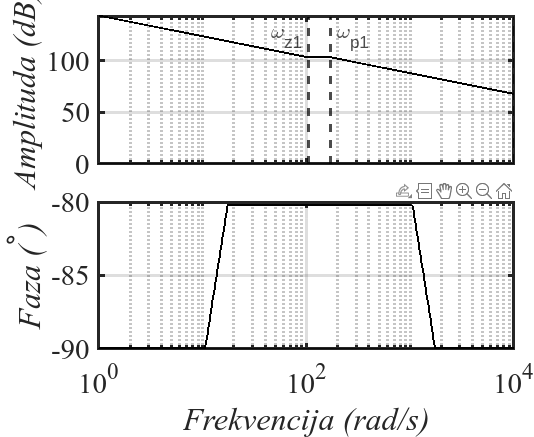


GR = tf([KR, KR/Ti], [1, 0]); 

G_full = GR * Gp;

w = logspace(0, 4, 1000);
draw_bode(G_full, w);

## Regulator (simetricni optimum, standardno):

% Ulazni parametri:
Gp = Gp_ccm_mpp;
param = ccm_sys_const_mpp;
Mp = 0.20;
%%%%%%%%%%%%%%%%%%

a = 3.57;
Kp = param.K;
wp = 1/param.Tn

wp = 171.8131


wc = wp/a

wc = 48.1269

wi = wc/a

wi = 13.4809


Ti = abs(1/wi)

Ti = 0.0742

KR = ((wc^2)*sqrt(wp^2 + wc^2))/(Kp*sqrt(wi^2 + wc^2))

KR = -4.4560e+03

## PID tuner:

KR = PI.Kp

KR = -3.9464

Ti = PI.Kp/PI.Ki

Ti = 0.0036

## Bode:

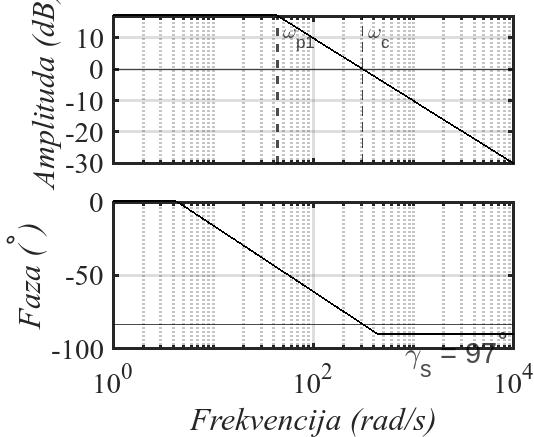

w = logspace(0, 4, 1000);
draw_bode(Gp_ccm_mpp, w);

## PV ulazni param:

pv_in.G = 1000;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_in.G = 1000; 
pv_1000 = calc_pv_res("Solar_v2", pv_in);
pv_in.G = 500;
pv_500 = calc_pv_res("Solar_v2", pv_in);
pv_in.G = 200;
pv_200 = calc_pv_res("Solar_v2", pv_in);

pv_1000.G = 1000;
pv_500.G = 500;
pv_200.G = 200;

## PV U-I karakteristika:

pv_list = {pv_1000, pv_500, pv_200};
colors = {'b', 'r', [1, 0.5, 0]};

fig = plot_pv_characteristics(pv_list, colors)

fig =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1299 1063]
       Units: 'pixels'

  Show all properties


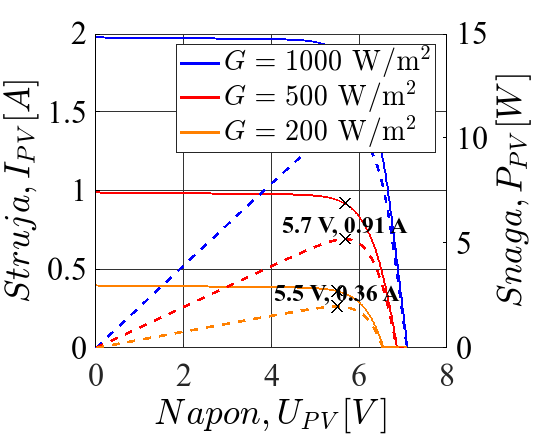

exportgraphics(gcf, picture_path + "/pv_irradiance_characteristics.png", 'Resolution', 300);

## PV P-U karakteristika:

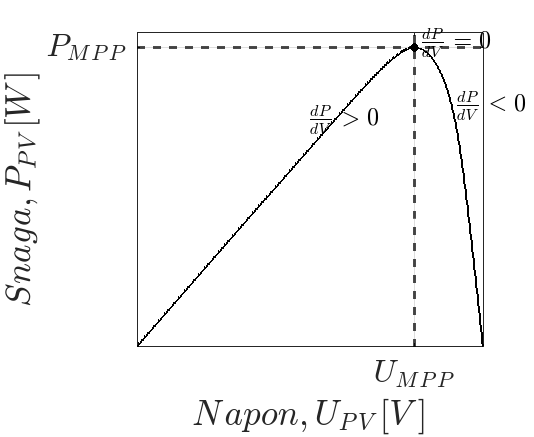

% Figure size ~11x9 cm
width_px = round(11/2.54 * 300);
height_px = round(9/2.54 * 300);
fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]);

% Font settings
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

plot(pv_1000.Upv, pv_1000.Ppv, '-k', 'LineWidth', 2);  % <-- main P-V plot
hold on;

% Grid settings (make it pronounced)
grid on;

% MPP guide lines
yline(pv_1000.Pmpp, '--k', 'LineWidth', 1.6);
xline(pv_1000.Umpp, '--k', 'LineWidth', 1.6);

% Axis labels
xlabel('${Napon, U_{PV} [V]}$', 'Interpreter', 'latex');
ylabel('${Snaga, P_{PV} [W]}$', 'Interpreter', 'latex');

% --- Set only Umpp and Pmpp as ticks ---
xticks(pv_1000.Umpp);
yticks(pv_1000.Pmpp);

xticklabels({'$U_{MPP}$'});
yticklabels({'$P_{MPP}$'});
set(gca, 'TickLabelInterpreter', 'latex');

% Tick appearance
ax.TickLength = [0.015 0.015];
ax.TickLabelInterpreter = 'latex';
ax.TickLabelInterpreter = 'latex';

grid on;
% Add MPP marker
plot(pv_1000.Umpp, pv_1000.Pmpp, 'ok', 'MarkerFaceColor', 'k', 'MarkerSize', 6);

% --- Annotations ---
text(pv_1000.Umpp + 0.1, pv_1000.Pmpp + 0.2, ...
     "$\frac{dP}{dV} = 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

text(pv_1000.Umpp - 2.2, pv_1000.Pmpp - 2.5, ...
     "$\frac{dP}{dV} > 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

text(pv_1000.Umpp + 0.8, pv_1000.Pmpp - 2.0, ...
     "$\frac{dP}{dV} < 0$", ...
     'Interpreter', 'latex', 'FontSize', 18);

% Limits
xlim([0, max(pv_1000.Upv)]);
ylim([0, max(pv_1000.Ppv)*1.05]);

% Grid again, just to be safe
grid on;


% Ensure text is black
exportgraphics(gcf, picture_path + "/pv_incremental_conductance.png", 'Resolution', 300);